clear all, close all, clc

## Prob-2.1a

The sequence here is of manufacturer- L, M, N, K

Q = [43, 37, 28, 55];       % quantity of RTD from man' L, M, N, K
T = sum(Q)                  % total no. of RTD

T = 163

So, if we pick one RTD, the probability it will be from manufacturers L, M, N, K, are-

P_K = Q/T

P_K =     0.2638    0.2270    0.1718    0.3374


Now, from concept of Poisson distribution, we get: $\mu \;=\lambda \;N$

N = 350;                        % No. of trials
lam = [1.1e-1, 6.2e-2, 2.5e-3, 7e-1];       % failure rates; d^-1
mu = lam *N                         % avg. failures from each manuf'

mu =    38.5000   21.7000    0.8750  245.0000


Now, from Poisson distribution, we know, if n failure is to be obserbed, its probability


$$P\left(n,\mu \;\right)=P\left(F_i \right)=\frac{e^{-\mu \;} \mu {\;}^n }{n!}$$


Let's find the probability of this- 6 fail outta 350 trial- coming from each manufacturers group-

n = 6;
    fn = factorial(n);
P_f_K = exp(-mu) .*mu.^n /fn

P_f_K = 1.0e-03 *

    0.0000    0.0546    0.2598    0.0000


So, let's find the total probability of failure- by combining it with picking-probab'

    P_f_KT = P_f_K .* P_K      % the array shows individual values

P_f_KT = 1.0e-04 *

    0.0000    0.1240    0.4464    0.0000


P_fT = sum(P_f_KT)

P_fT = 5.7030e-05

Now, from Bayes theorem, we have


$$P{\left(K_N |F\right)}=\frac{\left.P{\left(K_N \right)}\ P\left(F\right|K_N \right)}{\sum_1^N \left.P\left(K_i \right)P\left(F\right|K_i \right)}=\frac{\left.P{\left(K_N \right)}\ P\left(F\right|K_N \right)}{P\left(F\right)}$$


Then, the probability, that it came from manufacturer N is

P_N_F = P_K(3)* P_f_K(3) /P_fT

P_N_F = 0.7827

(Ans)

## Prob-2.1b

Let's repeat the algorithm of above problem-

Q = [43, 37, 28];           % quantity of RTD from man' L, M, N
T = sum(Q)                  % total no. of RTD

T = 108

So, if we pick one RTD, the probability it will be from manufacturers L, M, N, K, are-

P_K = Q/T

P_K =     0.3981    0.3426    0.2593


Now, from concept of Poisson distribution, we get: $\mu \;=\lambda \;N$

Now, from concept of Poisson distribution, we get: $\mu \;=\lambda \;N$

N = 350;                            % No. of trials
lam = [1.1e-1, 6.2e-2, 2.5e-3];       % failure rates; d^-1
mu = lam *N                         % avg. failures from each manuf'

mu =    38.5000   21.7000    0.8750


Now, from Poisson distribution, we know, if n failure is to be obserbed, its probability


$$P\left(n,\mu \;\right)=P\left(F_i \right)=\frac{e^{-\mu \;} \mu {\;}^n }{n!}$$


Let's find the probability of this- 6 fail outta 350 trial- coming from each manufacturers group-

n = 6;
    fn = factorial(n);
P_f_K = exp(-mu) .*mu.^n /fn

P_f_K = 1.0e-03 *

    0.0000    0.0546    0.2598


So, let's find the total probability of failure

    P_f_KT = P_f_K .* P_K      % the array shows individual values

P_f_KT = 1.0e-04 *

    0.0000    0.1871    0.6737


P_fT = sum(P_f_KT)

P_fT = 8.6074e-05

Now, from Bayes theorem, we have


$$P{\left(K_N |F\right)}=\frac{\left.P{\left(K_N \right)}\ P\left(F\right|K_N \right)}{\sum_1^N \left.P\left(K_i \right)P\left(F\right|K_i \right)}=\frac{\left.P{\left(K_N \right)}\ P\left(F\right|K_N \right)}{P\left(F\right)}$$


Then, the probability, that it came from L, M, N are-

P_K1_F = P_K(1)* P_f_K(1) /P_fT     % L

P_K1_F = 3.9835e-07

P_K2_F = P_K(2)* P_f_K(2) /P_fT     % M

P_K2_F = 0.2173

P_K3_F = P_K(3)* P_f_K(3) /P_fT     % N

P_K3_F = 0.7827

(Ans)

## Prob-2.1c

The probability difference here is-

df = P_N_F - P_K3_F

df = 1.1102e-16

(Ans)

## Prob-2.2a

Given,

mu_p = 90;            % mean wind velocity; 90 mph
CV = 0.2;             % coeff' of variance

As we know, $\textrm{CV}=\frac{\sigma }{\mu \;}$

sg_p = CV*mu_p          % Std

sg_p = 18

Now, for lognormal distribution, let's find the 'workable' mean and variance using the following equations-

$\mu =\ln \frac{\mu_p^2 }{\sqrt{\mu_p^2 +\sigma_p^2 }}$; $\sigma =\sqrt{\ln {\left(\frac{\sigma_p^2 }{\mu_p^2 }+1\right)}}$

Here, subscript p meas- prior

  dnm = sqrt(mu_p^2 + sg_p^2);
mu = log( mu_p^2 /dnm)              % mph

mu = 4.4802


sg = sqrt( log(sg_p^2 /mu_p^2 + 1)) % mph

sg = 0.1980

Now,  use these $\mu \;$and $\sigma \;$values from above in lognormal distribution. 

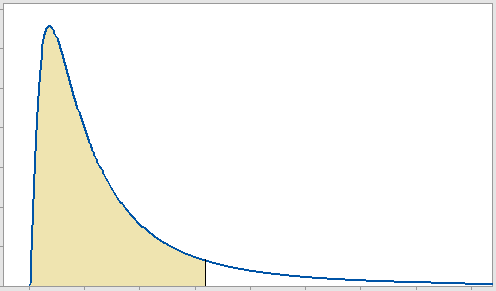

x = 120;                    % given max' wind; mph
p = logncdf(x, mu, sg);     % probab' up to that value

Then, probab' of exceedence-

px = 1 - p              % exceedance 

px = 0.0604

(Ans)

We can check this- finding probability from using distrbution 

p = lognpdf(x, mu, sg)

p = 0.0050

p = normpdf(x, mu_p, sg_p)

p = 0.0055

This shows, the probability values are nearby.

## Prob-2.2b

Given, 

lm = 1;             % frequency of tornado hitting; y^-1
T = 100;            % tornado return period; y
N = lm *T;          % total no. of tornado hit in T;
p_d = 1/N           % probability of design-base tornado

p_d = 0.0100

Now, let's plot the lognormal distribution of tornado-

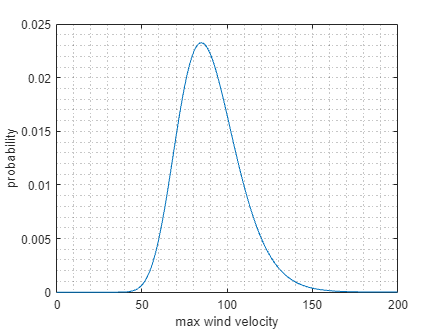

x = linspace(0,200,201);    % tornado wind velocity
p = lognpdf(x, mu, sg);

figure()
plot(x, p), grid minor
xlabel('max wind velocity')
ylabel('probability')

From the above curve, it is seen that at around 65 mph, the probability hits 0.01 

So, design tornado wind is 65 mph (Ans)

**Alternative Method**

by inverse lognormal function

x_d = logninv(p_d, mu, sg)

x_d = 55.6724

This shows that the design-base wind  velocity is 55.67 mph    

(Ans)

## Prob-2.3

Given,

P_A1 = 0.6;
P_A2 = 0.4;

So, from test B

P_F_A1 = 0.01;          % probability of bolt failing from lot A1
P_F_A2 = 0.03;          % ...from A2    

So, let's find thge total probability of failing using following equation-


$$P\left(H\right)=\sum_1^N \left.P\left(H\right|E_i \right)P\left(E_i \right)$$


P_F = P_A1 *P_F_A1 + P_A2 *P_F_A2       % probability of bolts failing

P_F = 0.0180

Now, let's find the probability of coming of failed bolts from individual lots.


$$P{\left(E_i |H\right)}=\frac{\left.P{\left(E_i \right)}\ P\left(H\right|E_i \right)}{\sum_1^N \left.P\left(E_k \right)P\left(H\right|E_k \right)}$$


P_A1_F = P_A1 *P_F_A1 /P_F          % probability of coming from lot A1 of failed bolts

P_A1_F = 0.3333

P_A2_F = P_A2 *P_F_A2 /P_F          % ....lot A2... 

P_A2_F = 0.6667

(Ans)

## Prob-2.4a

Given,

alf = 0.95;         % level of confidence
p = 0.05;           

We know, from engineering approach-


$$\alpha \;=1-{\left(\sum_0^m \frac{\mu^k }{k!}\right)}\exp \left(-\mu \right)$$


or, $1-\alpha ={\left(\sum_0^m \frac{\mu^k }{k!}\right)}\exp \left(-\mu \right)$

Let's find the RHS of of the above equation i.t.o u

syms u                  % average no. of failure
RHS = 0;
for k = 0:1:1
    fk = factorial(k);
 RHS = RHS + u^k/fk *exp(-u);
end

So, the RHS expression is-

RHS 

$$RHS = {\mathrm{e}}^{-u}+u\,{\mathrm{e}}^{-u}$$

Let's simplify the equation-

LHS = log(1-alf)

LHS = -2.9957

RHS1 = log(RHS)

$$RHS1 = \log\left({\mathrm{e}}^{-u}+u\,{\mathrm{e}}^{-u}\right)$$

Now, let's solve the equation for u (mu) to get average number of failures-

eqn = LHS == RHS1;
sol = solve(eqn, u);

u = double(sol)

u = 4.7439

So, we have

N = u/p             % no of trials

N = 94.8773

N = round(N)

N = 95

(Ans)

## Prob-2.4b

Given,

N = 89;             % no. of trials
n = 1;              % failure
x_b = n/N           % failure probable

x_b = 0.0112

For one sided 95% confidence

alf = 0.95;             % Confidence level
alf = 0.90;             % CL equivalent for one-sided interval
ar = (1 + alf)/2;       % area for calculating z-score
dl = norminv(ar)        % z-score, dl

dl = 1.6449

dl_2 = dl^2;

We know the following from the CLT


$$p\left\lbrace \frac{{\overset{-}{x} }_n -\mu }{\sigma \;/\sqrt{\;N}}<\delta \right\rbrace =\alpha \;$$


This could be simplified as:  ${\left(\bar{x} -p\right)}^2 \;N<{\;\delta \;}^2 \left(p-p^2 \right)$

Now, let's solve the inequality

syms p real

ineq = (x_b - p)^2 *N < dl_2*(p - p^2);
sol = solve(ineq, p, 'ReturnConditions',true);     % 1 for true
sol.p(1);           % not nec'
res = sol.conditions;       % results ITO conditions
res = vpa(res)              % num' approx' of results

$$res = x<0.048800781179922783183634177910734\wedge 0.0025106584218810505373077630928174<x$$

So, we see that, p = [ 0.0488 - 0.00251 ]

For the one-sided consideration, p = 0.0488     (Ans)

## Prob-2.4c

For Chi square distribution

et = 2*(n+1)            % degrees of freedom, DOF

et = 4

alf = 0.95;             % level of confidence, CL

So, from inverse cumilitive function, we gaet $\chi {\;}^2$ value-

ch2 = chi2inv(alf,et)       % chi-square value for CL and DOF

ch2 = 9.4877

ch = sqrt(ch2)

ch = 3.0802

Then the upper limit of probability

p = ch2 /(2*N)

p = 0.0533

(Ans) 